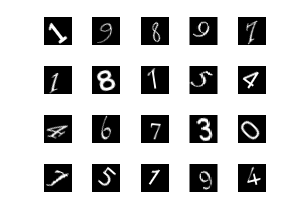

%%  程序说明
% 实例 4.1-1
% 功能：对含有0~9数字的二值图像（像素为28×28）进行分类，并计算分类准确率
% 作者：zhaoxch_mail@sina.com
% 时间：2020年2月22日
% 版本：DLTEX1-V1
% 注：1）本实例主要用于说明如何构建网络？如何改变网络结构及网络结构改变后的影响。所以，请重点关注步骤3
%     2）做一些网络结构的调整主要改变步骤3中的相关参数设置即可
%     3）读者可以结合注释（%之后的语句）对程序进行理解
%
% 在本例中如何改变网络的结构?
% 1)去掉批量归一化层看效果：分别在第一个batchNormalizationLayer（第41行）、分别在第二个batchNormalizationLayer（第46行）所对应的语句之前加%，将其注释掉
% 2)去掉一个卷积层看效果：分别在第卷积层2（第45行）、批量归一化层2（第46行）、非线性激活函数2（第47行）、池化层2（第48行）所对应的语句之前加%，将其注释掉
% 3)去掉一个卷积层之后，减少卷积核的数量看效果：在2）的基础上，将卷积层1的卷积核的个数改为4（将40行，函数中第2个参数8改为4）。

%% 清除内存、清除屏幕
clear
clc

%% 步骤1：加载图像样本数据，并显示其中的部分图像（本节不重点讲解）
digitDatasetPath = fullfile(matlabroot,'toolbox','nnet','nndemos', ...
    'nndatasets','DigitDataset');
imds = imageDatastore(digitDatasetPath, ...
    'IncludeSubfolders',true,'LabelSource','foldernames');
figure;
perm = randperm(10000,20);
for i = 1:20
    subplot(4,5,i);
    imshow(imds.Files{perm(i)});
end

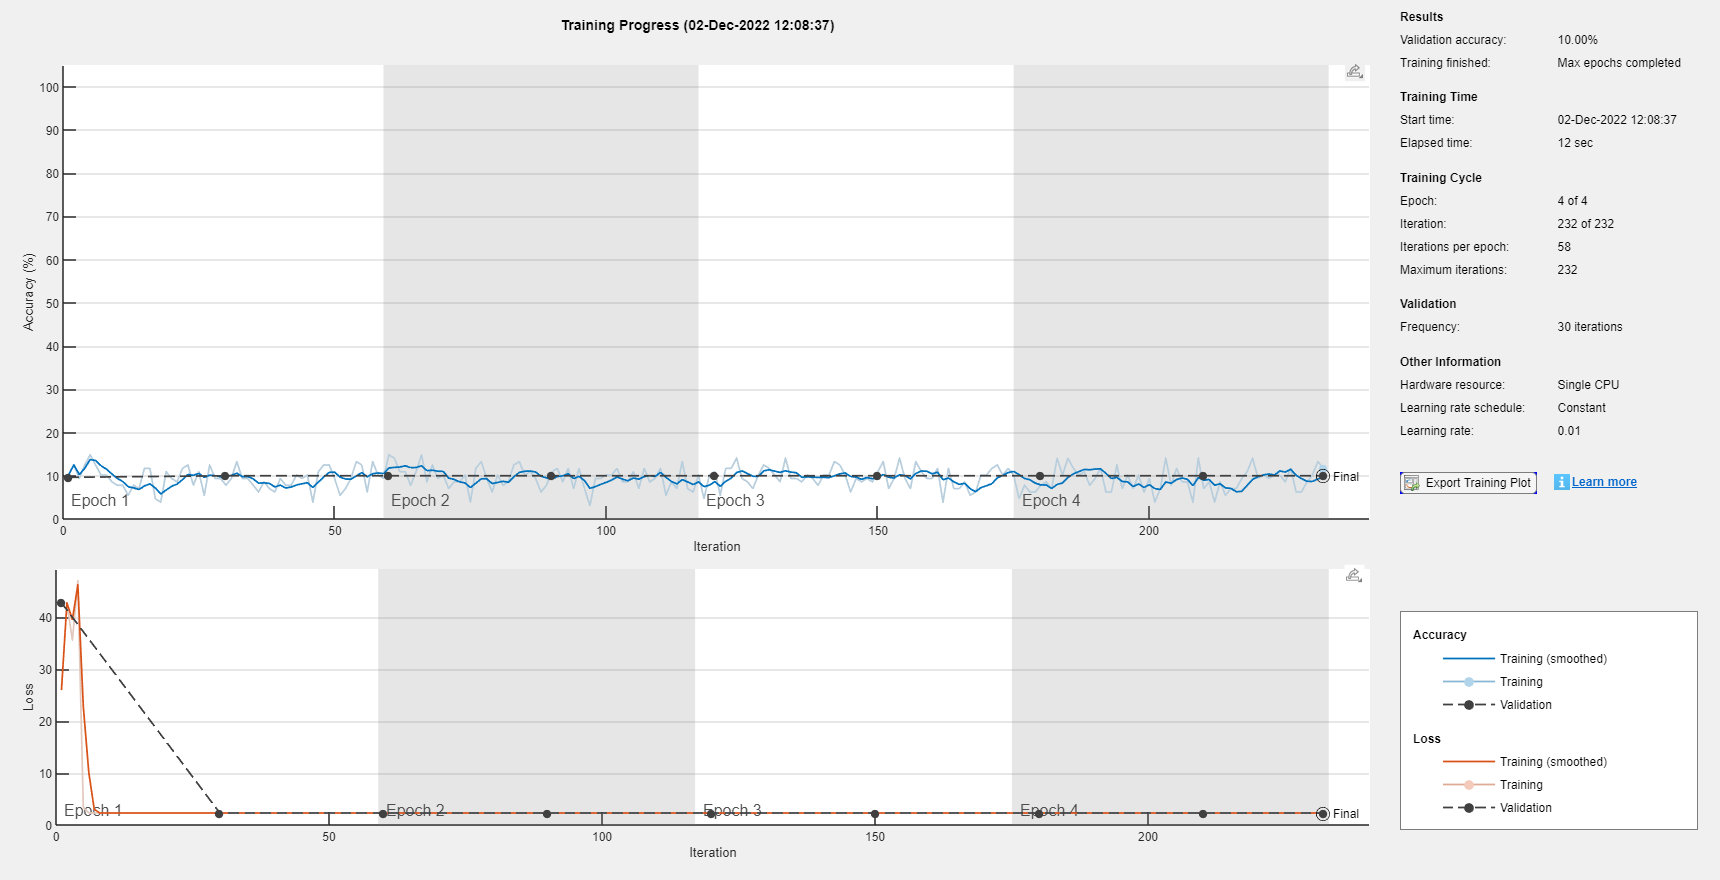


%% 步骤2：将加载的图像样本分为训练集和测试集（注：在本例中，训练集的数量为750幅，剩余的为测试集）【本节不重点讲解】
numTrainFiles = 750;
[imdsTrain,imdsValidation] = splitEachLabel(imds,numTrainFiles,'randomize');

%% 步骤3：构建卷积网络（注：可以在该部分进行相关参数的设置改进）【本节重点讲解的部分】
layers = [
    imageInputLayer([28 28 1])                  % 输入层，1个通道，像素为28×28
    
    convolution2dLayer([3 3],4,'Padding','same')% 卷积层1：卷积核大小为3×3，卷积核的个数为8（每个卷积核的通道数与输入图像的通道数相等，本层中每个卷积核1个通道）卷积的方式采用零填充方式（即设定为same方式）
%     batchNormalizationLayer                     % 批量归一化层1
    reluLayer                                   % ReLu非线性激活函数1
    maxPooling2dLayer(2,'Stride',2)             % 池化层1：池化方式：最大池化；池化区域为2×2，步长为2
    
   convolution2dLayer([3 3],16,'Padding','same')% 卷积层2：卷积核大小为3×3，卷积核的个数为16（每个卷积核的通道数与输入特征图的通道数相等，本层中每个卷积核8个通道）卷积的方式采用零填充方式（即设定为same方式）
%    batchNormalizationLayer                      % 批量归一化层2
   reluLayer                                    % ReLu非线性激活函数2
   maxPooling2dLayer(2,'Stride',2)              % 池化层2：池化方式：最大池化；池化区域为2×2，步长为2
    
    fullyConnectedLayer(10)                     % 全连接层：将全连接层输出的个数设置为10个
    softmaxLayer                                % softmaxLayer层：输出每个输出的概率
    classificationLayer ];                       % 分类层：根据上一层的输入的概率，进行分类并输出

%% 步骤4：配置训练选项并开始训练（相关的训练函数将在4.2节中进行详细介绍）【本节不重点讲解】
    options = trainingOptions('sgdm', ...
    'InitialLearnRate',0.01, ...
    'MaxEpochs',4, ...
    'Shuffle','every-epoch', ...
    'ValidationData',imdsValidation, ...
    'ValidationFrequency',30, ...
    'Verbose',false, ...
    'Plots','training-progress');                % 配置训练选项
                                                 %'sgdm'表示使用具有动量的随机梯度下降方法来训练网络；'InitialLearnRate'设置初始学习率为0.01；'MaxEpochs'将最大训练轮数设置为4；'Shuffle'表示打乱数据，'every-epoch'则代表每一轮训练都打乱一次数据；'ValidationData'用于设置验证数据集，'ValidationFrequency'设置验证频率为30；'Verbose'设置为false则不显示进度信息；'Plots'打开训练进度图。

    net = trainNetwork(imdsTrain,layers,options); %对网络进行训练

    
   %% 步骤5：将训练好的网络用于对新的输入图像进行分类，并计算准确率【本节不重点讲解】
   YPred = classify(net,imdsValidation);
   YValidation = imdsValidation.Labels;
   accuracy = sum(YPred == YValidation)/numel(YValidation)

accuracy = 0.1000

   %% 
   %% 


i=imread("number0.png")

i = 28×28×3 uint8 array
i(:,:,1) =

     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     

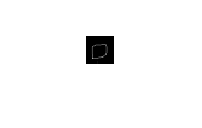

figure, imshow(i)

ig=reshape(rgb2gray(i),[28 28 1]);
classify(net,ig)

ans = categorical
     1 
